# Problem 6

max = 50;
N = 4;
x_max = max;
x_step = 2*max/N;
y_max = max;
y_step = 2*max/N;
z_max = max;
z_step = 2*max/N;
[y0_x, y0_y, y0_z] = meshgrid(-x_max:x_step:x_max, -y_max:y_step:y_max, -z_max:z_step:z_max);
% [y0_x, y0_y] = meshgrid(-x_max:x_step:x_max, -y_max:y_step:y_max);

xsize = size(y0_x);
ysize = size(y0_y);
zsize = size(y0_z);
y0 = [reshape(y0_x, 1,xsize(1)*xsize(2)*xsize(3));
      reshape(y0_y, 1,ysize(1)*ysize(2)*ysize(3));
      reshape(y0_z, 1,zsize(1)*zsize(2)*zsize(3))];

tspan = [0 10];

clf;
figure(1)
hold on
[sx, sy, sz] = sphere;

sx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483    0.0000    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483    0.0000   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564
   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955    0.0000    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955    0.0000   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090
   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403    0.0000    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403    0.0000   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540
   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816    0.0000    0.1816    0.3455    0.4755    0.5590    0.5878    0.5590    0.4755    0.3455    0.1816 

sy =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483         0    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483         0
         0   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955         0    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955         0
         0   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403         0    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403         0
         0   -0.1816   -0.3455   -0.4755   -0.5590   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816         0    0.1816    0.3455    0.4755    0.5590 

sz =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877
   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511
   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910
   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090 

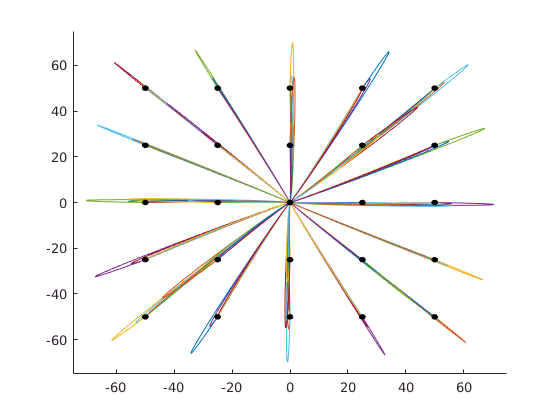

for i=1:length(y0)
   y_init = y0(:,i);
   [t, y] = ode45(@my_ode,tspan,y_init);
   plot3(y(:,1), y(:,2), y(:,3));
   surf(sx+y(1,1),sy+y(1,2), sz+y(1,3));
end
axis([-max max -max max -max max]*1.5)


% ODE function

function [yout] = my_ode(t, yin)
  x = yin(1);
  y = yin(2);
  z = yin(3);
  
  xdot = y + x*z;
  ydot = -x -y + y*z;
  zdot = -x^2 - y^2;

  yout = [xdot; ydot; zdot];

end